2.3

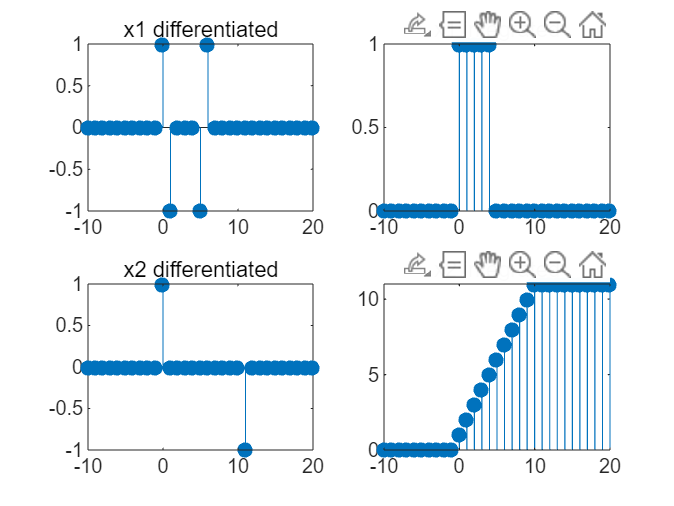

clear;
clc;


function y = integrate(x) %   y[n] = y[n-1] + T*x[n], with y[-1] = 0.
    T = 1;
    y = filter(T, [1 -1], x);
end

function y = differ(x) %   y[n] = (x[n] - x[n-1]) / T, with x[-1] = 0.
    T = 1;
    y = filter([1 -1] / T, 1, x);
end


n = -10:20;

x1 = zeros(size(n));
x1(n == 0) = 1;
x1(n == 5) = -1;


x2 = zeros(size(n));
x2 = 1*(n >= 0) - 1*(n >= 11);
x2

y1_diff = differ(x1);
y1_integrate = integrate(x1);

y2_diff = differ(x2);
y2_integrate = integrate(x2);

figure;
subplot(2,2,1)
stem(n,y1_diff,"filled");
title("x1 differentiated");
subplot(2,2,2);
stem(n,y1_integrate,"filled")
title("x1 integrated");
subplot(2,2,3)
stem(n,y2_diff,"filled");
title("x2 differentiated");
subplot(2,2,4);
stem(n,y2_integrate,"filled")
title("x2 integrated");

2.4

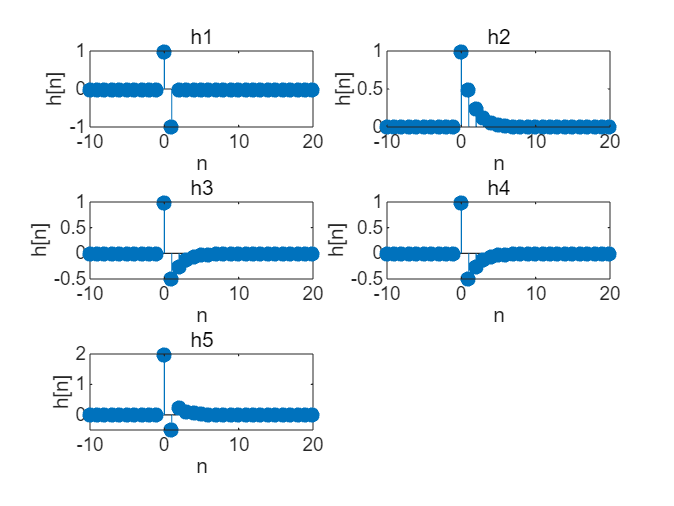

function y = S1(x) % y[n] = x[n] - x[n-1]
y = filter([1 -1], 1, x);
end

function y = S2(x) % y[n] = 0.5*y[n-1] + x[n]
y = filter(1, [1 -0.5], x);
end

delta = zeros(size(n));
delta(n == 0) = 1;

h1 = S1(delta);
h2 = S2(delta);
h3 = S1(S2(delta));
h4 = S2(S1(delta));
h5 = S1(delta) + S2(delta);

impulse_response = {h1 h2 h3 h4 h5};

figure;
for k = 1:5
    subplot(3,2,k);
    stem(n,impulse_response{k}, 'filled'); 
    xlabel('n');
    ylabel('h[n]');
    title("h" + k);
end

2.5

music = audioread("music.au");


music_1 = S1(music);
music_2 = S2(music);

sound(music_1);

2.6

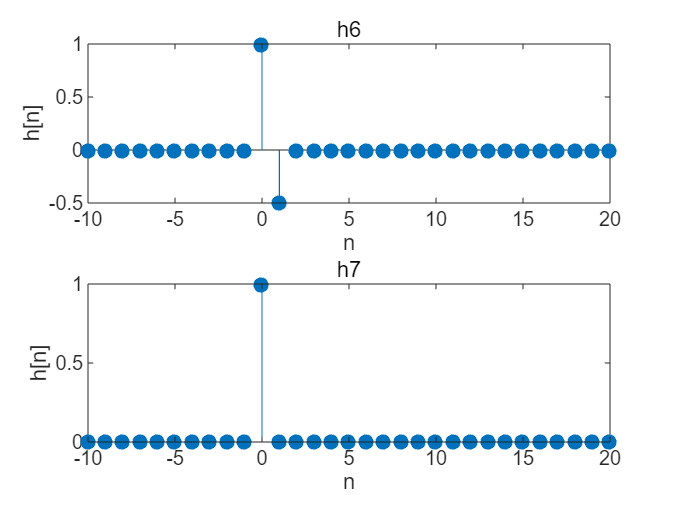

function y = S3(x) % y[n] = x[n] - 0.5*x[n-1].
y = filter([1 -0.5], 1, x);
end

h6 = S3(delta);
h7 = S3(S2(delta));

figure;

subplot(2,1,1);
stem(n,h6, 'filled'); 
xlabel('n');
ylabel('h[n]');
title("h6");

subplot(2,1,2);
stem(n,h7, 'filled'); 
xlabel('n');
ylabel('h[n]');
title("h7");

2.7

systems = {@bbox1, @bbox2, @bbox3};
names   = {'bbox1', 'bbox2', 'bbox3'};

N   = 300;       
M   = 10;        
add_zero = 80;        % 补零

n  = 0:N-1;
x1 = sin(2*pi*0.04*n) + 0.3*randn(1,N);
x2 = cos(2*pi*0.07*n) + 0.2*randn(1,N);
a  = 1.4;
b  = -0.6;

x_ti = [zeros(1,add_zero), randn(1,N), zeros(1,add_zero)];

err_linear = zeros(1,3);
err_time  = zeros(1,3);


for k = 1:3
    S = systems{k};
    
    % linear
    y1    = S(x1);              y1    = y1(:).';
    y2    = S(x2);              y2    = y2(:).';
    y_sum = S(a*x1 + b*x2);     y_sum = y_sum(:).';
    y_lin = a*y1 + b*y2;
    
    L = min([length(y_sum), length(y_lin)]);
    err_linear(k) = norm(y_sum(1:L) - y_lin(1:L)) / ...
                 norm(y_sum(1:L));
    
    % time invariance
    y   = S(x_ti);              y   = y(:).';
    Lx  = length(x_ti);
    Ly  = length(y);
    
    % 延迟
    x_delay = [zeros(1,M), x_ti(1:end-M)];
    y_delay = S(x_delay);       y_delay = y_delay(:).';
    
    Ld = min(length(y_delay), Ly) - M;
    err_d = norm(y_delay(M+1:M+Ld) - y(1:Ld)) / ...
            norm(y(1:Ld));
    
    % 超前
    x_adv = [x_ti(M+1:end), zeros(1,M)];
    y_adv = S(x_adv);           y_adv = y_adv(:).';
    
    La = min(length(y_adv), Ly) - M;
    err_a = norm(y_adv(1:La) - y(M+1:M+La)) / ...
            max(norm(y(M+1:M+La)), eps);
    
    err_time(k) = max(err_d, err_a);
    
    fprintf('%s: 线性误差 = %.3e, 时不变误差 = %.3e\n', ...
            names{k}, err_linear(k), err_time(k));
end

bbox1: 线性误差 = 1.369e-16, 时不变误差 = 1.381e+00
bbox2: 线性误差 = 1.405e-16, 时不变误差 = 0.000e+00
bbox3: 线性误差 = 4.399e-01, 时不变误差 = 0.000e+00


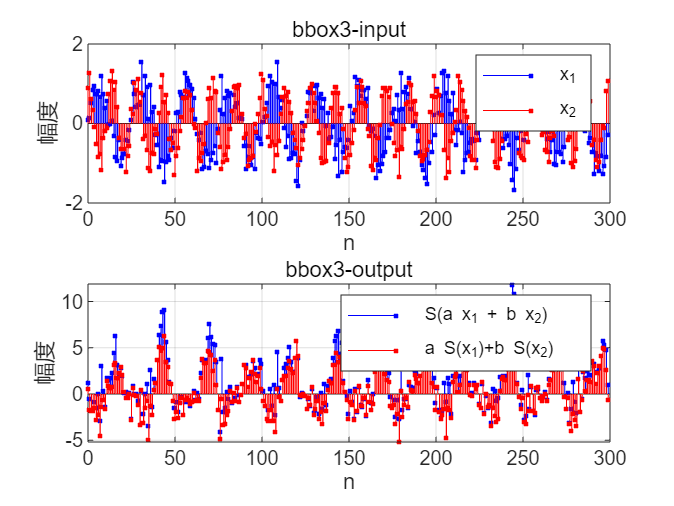


[~, idx_nonlin]  = max(err_linear);
[~, idx_timevar] = max(err_time);

k = idx_nonlin;
S = systems{k};

y1    = S(x1);              y1    = y1(:).';
y2    = S(x2);              y2    = y2(:).';
y_sum = S(a*x1 + b*x2);     y_sum = y_sum(:).';
y_lin = a*y1 + b*y2;

L = min([length(y_sum), length(y_lin)]);
nplot = 0:L-1;

figure('Name', ['非线性测试 - ' names{k}]);

subplot(2,1,1);
stem(nplot, x1(1:L), 'b.'); hold on;
stem(nplot, x2(1:L), 'r.');
legend('x_1','x_2');
title('bbox3-input');
xlabel('n'); ylabel('幅度'); grid on;

subplot(2,1,2);
stem(nplot, y_sum(1:L), 'b.'); hold on;
stem(nplot, y_lin(1:L), 'r.');
legend('S(a x_1 + b x_2)','a S(x_1)+b S(x_2)');
title('bbox3-output');
xlabel('n'); ylabel('幅度'); grid on;

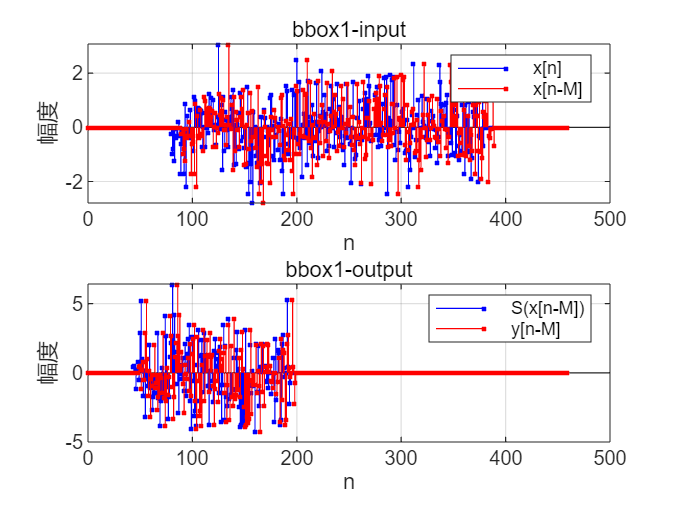



k = idx_timevar;
S = systems{k};

y   = S(x_ti);              y   = y(:).';
Lx  = length(x_ti);

x_delay = [zeros(1,M), x_ti(1:end-M)];
y_delay = S(x_delay);       y_delay = y_delay(:).';
y_delay_expected = [zeros(1,M), y(1:end-M)];


x_adv = [x_ti(M+1:end), zeros(1,M)];
y_adv = S(x_adv);           y_adv = y_adv(:).';
y_adv_expected = [y(M+1:end), zeros(1,M)];

nplot = 0:Lx-1;
figure('Name', ['时不变测试 - ' names{k}]);

subplot(2,1,1);
stem(nplot, x_ti, 'b.'); hold on;
stem(nplot, x_delay, 'r.');
legend('x[n]','x[n-M]');
title('bbox1-input');
xlabel('n'); ylabel('幅度'); grid on;

subplot(2,1,2);
stem(nplot, y_delay, 'b.'); hold on;
stem(nplot, y_delay_expected, 'r.');
legend('S(x[n-M])','y[n-M]');
title('bbox1-output');
xlabel('n'); ylabel('幅度'); grid on;

2.8

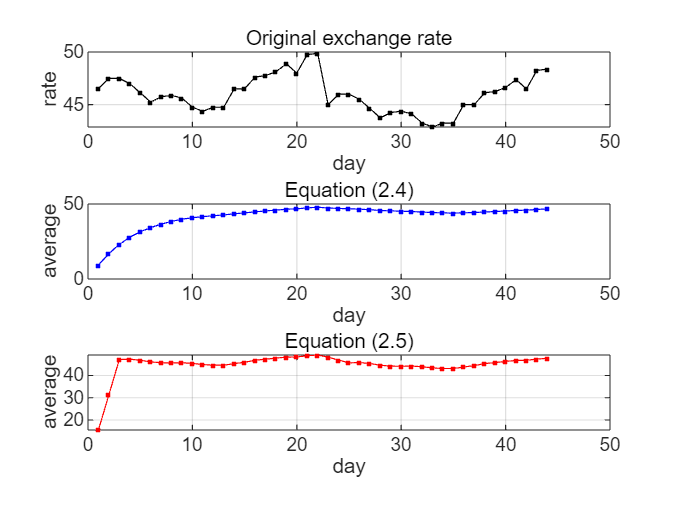

function y = stock_2_4(x, initialOutput) %   y[n] = 0.8*y[n-1] + 0.2*x[n].

wasRow = (size(x, 1) == 1);
xColumn = x(:);
yColumn = zeros(size(xColumn));
previous = initialOutput;

for n = 1:length(xColumn)
    yColumn(n) = 0.8 * previous + 0.2 * xColumn(n);
    previous = yColumn(n);
end

if wasRow
    y = yColumn.';
else
    y = yColumn;
end
end

function y = stock_2_5(x, initialOutput, pastInputs) %   y[n] = y[n-1] + (x[n] - x[n-3])/3.

wasRow = (size(x, 1) == 1);
xColumn = x(:);
extendedInput = [pastInputs(:); xColumn];
yColumn = zeros(size(xColumn));
previous = initialOutput;

for n = 1:length(xColumn)
    delayedByThree = extendedInput(n);
    yColumn(n) = previous + (xColumn(n) - delayedByThree) / 3;
    previous = yColumn(n);
end

if wasRow
    y = yColumn.';
else
    y = yColumn;
end
end



stockData = load('stockrates.mat');
rate = stockData.rate(:).';
day = 1:length(rate);

average24 = stock_2_4(rate, 0);
average25 = stock_2_5(rate, 0, [0 0 0]);

figure;
subplot(3,1,1);
plot(day, rate, 'k.-'); grid on;
xlabel('day'); ylabel('rate'); title('Original exchange rate');
subplot(3,1,2);
plot(day, average24, 'b.-'); grid on;
xlabel('day'); ylabel('average'); title('Equation (2.4)');
subplot(3,1,3);
plot(day, average25, 'r.-'); grid on;
xlabel('day'); ylabel('average'); title('Equation (2.5)');

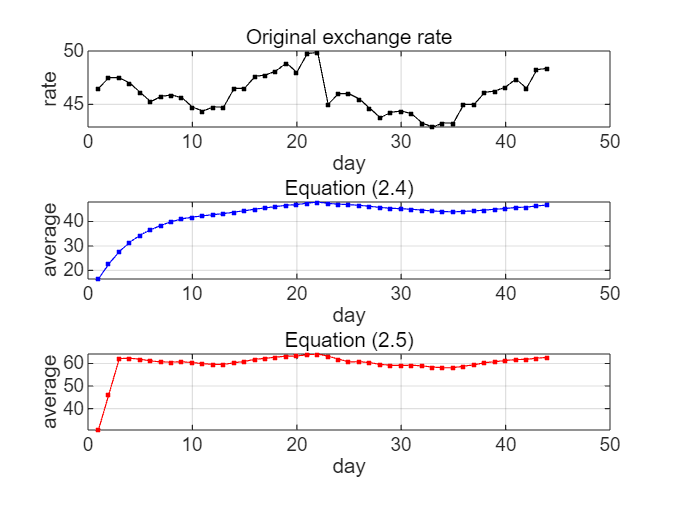


average24_1 = stock_2_4(rate, 9);
average25_1 = stock_2_5(rate, 15, [0 0 0]);
figure;
subplot(3,1,1);
plot(day, rate, 'k.-'); grid on;
xlabel('day'); ylabel('rate'); title('Original exchange rate');
subplot(3,1,2);
plot(day, average24_1, 'b.-'); grid on;
xlabel('day'); ylabel('average'); title('Equation (2.4)');
subplot(3,1,3);
plot(day, average25_1, 'r.-'); grid on;
xlabel('day'); ylabel('average'); title('Equation (2.5)');